# XTD_A6: Interval Decoding Port Entry Decode D TransMat

% NOTE: This is written to run with PokeIn Alignment ONLY

% load('.\XTD_WT_PI_PO_RawLFP.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_All_PO_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_DL_PI_PO.mat');

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH>
rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);

objTimeVect = mlb.obsvTimeVect-mlb.obsvTimeVect(1);

trlStrtWinDur = 2800;

pos2check = 4;

## Compile Data

trInt_DecTrlTransMat = cell(mlb.seqLength,mlb.seqLength);
trIntCON_DecTrlTransMat = cell(mlb.seqLength,mlb.seqLength);
trIntCON2_DecTrlTransMat = cell(mlb.seqLength,mlb.seqLength);
trIntCON2_DecTrlTransMat_Peak = cell(mlb.seqLength,mlb.seqLength);
tempCon2 = [];
% Step through each animal's performance
for ani = 1:length(fileDirs)
    % Pull out temporary animal data
    curAni_TrialInfo_Pos = xtd_TrialInfo_POS{pos2check,ani};
    curAni_TrialInfo_All = xtd_TrialInfo_FULL{ani};
    curAni_SeqStarts = find([curAni_TrialInfo_All.Position]==1);
    curAni_TrialMask = mask_Trial{pos2check,ani};
    if strcmp(alignment{1}, 'PokeIn')
        curAni_IntMask = mask_PreInt{pos2check,ani};
        curAni_IntMaskCON = mask_PreIntCON{pos2check,ani};
    else
        curAni_IntMask = mask_PstInt{pos2check,ani};
        curAni_IntMaskCON =  mask_PstIntCON{pos2check,ani};
    end
%     curAni_D = xtd_D(pos2check,:,ani);
    curAni_D = xtd_HR(pos2check,:,ani);
    % Step through each trial
    for trl = 1:length(curAni_TrialInfo_Pos)
%         if (curAni_TrialInfo_Pos(trl).Performance ~= 1)
        if (curAni_TrialInfo_Pos(trl).Performance == 1)
            % Identify the sequence the 4 comes from
            curSeqStart = curAni_SeqStarts(find(curAni_SeqStarts<=curAni_TrialInfo_Pos(trl).TrialNum,1,'last'));
            curSeqVect = [curAni_TrialInfo_All(curSeqStart:curAni_TrialInfo_Pos(trl).TrialNum).Odor];
            osLog = mod(curSeqVect,10)~=1:pos2check;
            if sum(osLog)==0
                osPos = pos2check;
                osOdr = pos2check;
            else
                osPos = find(osLog);
                osOdr = mod(curSeqVect(osPos),10);
            end
            % Create a trial start window mask
            if strcmp(alignment{1}, 'PokeIn')
                curTrlStrtNdx = find(curAni_TrialMask(:,trl),1,'first');
            else
                curTrlStrtNdx = find(curAni_TrialMask(:,trl),1,'last');
            end
            replayMask = false(size(mlb.obsvTimeVect));
            replayMask(curTrlStrtNdx-(trlStrtWinDur/2/mlb.dsRate):curTrlStrtNdx+((trlStrtWinDur/2/mlb.dsRate)-1)) = true;
            tempReplay = nan(sum(replayMask),mlb.seqLength);
            tempReplay_CON = nan(sum(replayMask),mlb.seqLength);
            tempReplay_CON2 = nan(sum(replayMask),mlb.seqLength);
            tempReplay_CON2_PeakNDX = nan(1,mlb.seqLength);
            if strcmp(alignment{1}, 'PokeIn')
                curAni_IntMaskCON2 = find(curAni_IntMask(:,trl),1,'first');
%                 curAni_IntMaskCON2 = find(curAni_IntMask(:,trl),1,'last')-(1000/mlb.dsRate); % Position 1 interval train time (matching the other positions)
%                 curAni_IntMaskCON2 = find(curAni_IntMask(:,trl),1,'last')+1; % Port Entry Window
%                 curAni_IntMaskCON2 = find(curAni_IntMask(:,trl),1,'last')+6; % HC Decoding Window
%                 curAni_IntMaskCON2 = find(curAni_IntMask(:,trl),1,'last')+9; % Pre-Decision Window
%                 curAni_IntMaskCON2 = find(curAni_IntMask(:,trl),1,'last')+17; % Post-Decision Window
            else
                curAni_IntMaskCON2 = find(curAni_IntMask(:,trl),1,'last');
%                 curAni_IntMaskCON2 = find(curAni_IntMask(:,trl),1,'first') + (1000/mlb.dsRate); % Position 4 interval train time (matching other positions)
%                 curAni_IntMaskCON2 = find(curAni_TrialMask(:,trl),1,'first') + 17; % Post-Decision Window
%                 curAni_IntMaskCON2 = find(curAni_TrialMask(:,trl),1,'first') + 6; % Pre-Decision Window
            end
            for pos = 1:mlb.seqLength
                tempReplay(:,pos) = mean(curAni_D{pos}(replayMask, curAni_IntMask(:,trl),trl),2,'omitnan');
                tempReplay_CON(:,pos) = mean(curAni_D{pos}(replayMask, curAni_IntMaskCON(:,trl),trl),2,'omitnan');
%                 tempReplay_CON2(:,pos) = curAni_D{pos}(replayMask, curAni_IntMaskCON2,trl);
%                 tempReplay_CON2(:,pos) = smooth(curAni_D{pos}(replayMask, curAni_IntMaskCON2,trl),3);
                tempReplay_CON2(:,pos) = smooth(curAni_D{pos}(replayMask, curAni_IntMaskCON2,trl),'lowess');
                
                replayTime = mlb.obsvTimeVect(replayMask);
                tempRep = tempReplay_CON2(1:sum(replayMask(1:curAni_IntMaskCON2)),pos);
%                 if pos==1
%                     tempPeak = find(tempRep==max(tempRep));
%                 else
                    tempPeak = find(tempReplay_CON2(:,pos)==max(tempReplay_CON2(:,pos)));
%                 end
                tempReplay_CON2_PeakNDX(pos) = replayTime(tempPeak(randi(length(tempPeak))));
            end
            tempCon2 = [tempCon2,curAni_IntMaskCON2];
            trInt_DecTrlTransMat{osOdr,osPos} = cat(3,trInt_DecTrlTransMat{osOdr,osPos}, tempReplay);
            trIntCON_DecTrlTransMat{osOdr,osPos} = cat(3,trIntCON_DecTrlTransMat{osOdr,osPos}, tempReplay_CON);
            trIntCON2_DecTrlTransMat{osOdr,osPos} = cat(3,trIntCON2_DecTrlTransMat{osOdr,osPos}, tempReplay_CON2);
            trIntCON2_DecTrlTransMat_Peak{osOdr,osPos} = cat(3, trIntCON2_DecTrlTransMat_Peak{osOdr,osPos}, tempReplay_CON2_PeakNDX);
        end
    end
end

trialLIGHTlat = lat_PrtLight(2:end,:)';
% trialLIGHTlat = cell2mat(trialLIGHTlat(:)');
trialPIlat = lat_TrlStart(:);
% trialPIlat = cell2mat(trialPIlat(:)');
trialSIGlat = lat_RwdSig(:);
% trialSIGlat = cell2mat(trialSIGlat(:)');
trialPOlat = lat_TrlEnd(:);
% trialPOlat = cell2mat(trialPOlat(:)');
trialRWDlat = lat_Rwd(:);
% trialRWDlat = cell2mat(trialRWDlat(:)');
nxtTrlLats = lat_NextTrl(:);
% nxtTrlLats = cell2mat(nxtTrlLats(:)');
prevTrlLats = lat_PrevTrl(:);
% prevTrlLats = cell2mat(prevTrlLats(:)');

## Plot Things :fingerscrossed:

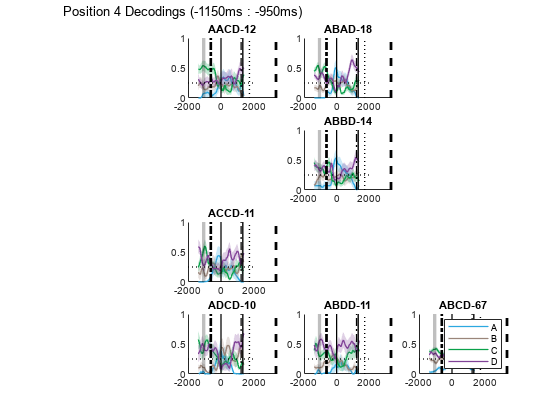

windowXticks = (trlStrtWinDur/2*-1:mlb.dsRate:(trlStrtWinDur/2-mlb.dsRate)) + mlb.dsRate/2;

figure;
% curTrInt = trInt_DecTrlTransMat;
% curTrInt = trIntCON_DecTrlTransMat;
curTrInt = trIntCON2_DecTrlTransMat;
spNdxs = reshape(1:numel(trInt_DecTrlTransMat), [mlb.seqLength, mlb.seqLength])';
for osT = 1:numel(trInt_DecTrlTransMat)
    if isempty(trInt_DecTrlTransMat{osT})
        continue;
    else
        subplot(mlb.seqLength, mlb.seqLength, spNdxs(osT));
        p = nan(1,mlb.seqLength);
        for pos = 1:mlb.seqLength
%             if strcmp(alignment{1}, 'PokeIn')
                p(pos) = mlb.PlotMeanVarLine(windowXticks,curTrInt{osT}(:,pos,:),3,0,mlb.PositionColors(pos,:));
%             else 
%                 if mod(pos+1,4) == 0
%                     pp = 4;
%                 else
%                     pp = mod(pos+1,4);
%                 end
%                 p(pos) = mlb.PlotMeanVarLine(windowXticks,curTrInt{osT}(:,pos,:),3,0,mlb.PositionColors(pp,:));
%             end
        end
        set(gca, 'ylim', [0 1]);
        if pos~=1
            plot(repmat(median(cell2mat(lat_PrtLight(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-.k', 'linewidth', 2);
%             plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
        end
        plot(repmat(median(cell2mat(lat_TrlStart(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-k', 'linewidth', 1);
        plot(repmat(median(cell2mat(lat_RwdSig(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-.k', 'linewidth', 1);
        plot(repmat(median(cell2mat(lat_TrlEnd(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-k', 'linewidth', 1);
        plot(repmat(median(cell2mat(lat_Rwd(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), ':k', 'linewidth', 1);
        plot(get(gca,'xlim'), [0.25 0.25],':k','linewidth', 1);
        if strcmp(endTrialBound, 'RWD')
            plot( repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
        elseif strcmp(endTrialBound, 'PO')
            plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
        elseif strcmp(endTrialBound, 'RS')
            plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
        end


        seqID = [mlb.Rosetta{1:mlb.seqLength}];
        [osO,osP] = ind2sub([mlb.seqLength, mlb.seqLength], osT);
        seqID(osP) = mlb.Rosetta{osO};
        title(sprintf('%s-%i',seqID,sum(~isnan(curTrInt{osT}(1,1,:)),3)));

        % For interval trained models
%         patch([mlb.obsvTimeVect(median(tempCon2))*mlb.sampleRate - mlb.binSize/2, mlb.obsvTimeVect(median(tempCon2))*mlb.sampleRate + mlb.binSize/2,...
%             mlb.obsvTimeVect(median(tempCon2))*mlb.sampleRate + mlb.binSize/2, mlb.obsvTimeVect(median(tempCon2))*mlb.sampleRate - mlb.binSize/2],...
%             [0 0 1 1], 'k', 'facealpha', 0.25, 'linestyle', 'none');
        % For model time trained models
        patch([mlb.obsvTimeVect(curAni_IntMaskCON2)*mlb.sampleRate - mlb.binSize/2, mlb.obsvTimeVect(curAni_IntMaskCON2)*mlb.sampleRate + mlb.binSize/2,...
            mlb.obsvTimeVect(curAni_IntMaskCON2)*mlb.sampleRate + mlb.binSize/2, mlb.obsvTimeVect(curAni_IntMaskCON2)*mlb.sampleRate - mlb.binSize/2],...
            [0 0 1 1], 'k', 'facealpha', 0.25, 'linestyle', 'none');
    end
end
legend(p,mlb.Rosetta(1:mlb.seqLength));
% For interval trained models
% annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
%     'String', sprintf('Position %i Decodings (Interval)',pos2check),...
%     'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');
% For model time trained models
annotation(gcf,'textbox', [0.1 0.95 0.9 0.05],...
    'String', sprintf('Position %i Decodings (%.00fms : %.00fms)',pos2check, mlb.obsvTimeVect(curAni_IntMaskCON2)*mlb.sampleRate - mlb.binSize/2, mlb.obsvTimeVect(curAni_IntMaskCON2)*mlb.sampleRate + mlb.binSize/2),...
    'FontSize',10, 'edgecolor', 'none', 'horizontalalignment', 'left');

## Plot mean peak decoding indices

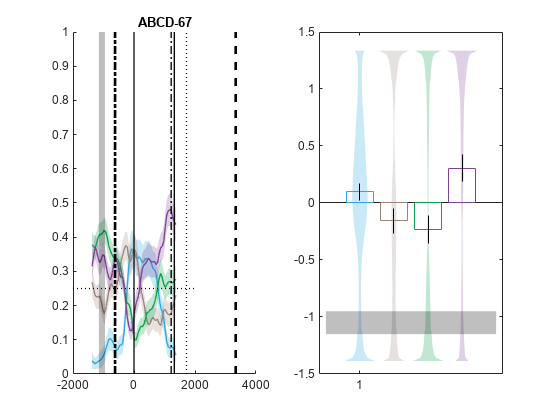

figure;
subplot(1,2,1)
for pos = 1:mlb.seqLength
%             if strcmp(alignment{1}, 'PokeIn')
    p(pos) = mlb.PlotMeanVarLine(windowXticks,trIntCON2_DecTrlTransMat{pos2check,pos2check}(:,pos,:),3,0,mlb.PositionColors(pos,:));
%             else
%                 if mod(pos+1,4) == 0
%                     pp = 4;
%                 else
%                     pp = mod(pos+1,4);
%                 end
%                 p(pos) = mlb.PlotMeanVarLine(windowXticks,curTrInt{osT}(:,pos,:),3,0,mlb.PositionColors(pp,:));
%             end
end
set(gca, 'ylim', [0 1]);
if pos~=1
    plot(repmat(median(cell2mat(lat_PrtLight(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-.k', 'linewidth', 2);
%             plot(repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
end
plot(repmat(median(cell2mat(lat_TrlStart(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-k', 'linewidth', 1);
plot(repmat(median(cell2mat(lat_RwdSig(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-.k', 'linewidth', 1);
plot(repmat(median(cell2mat(lat_TrlEnd(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), '-k', 'linewidth', 1);
plot(repmat(median(cell2mat(lat_Rwd(pos,:)), 'omitnan'), [1,2])*1000, get(gca,'ylim'), ':k', 'linewidth', 1);
plot(get(gca,'xlim'), [0.25 0.25],':k','linewidth', 1);
if strcmp(endTrialBound, 'RWD')
    plot( repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
elseif strcmp(endTrialBound, 'PO')
    plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
elseif strcmp(endTrialBound, 'RS')
    plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2])*1000, get(gca, 'ylim'), '--k', 'linewidth', 2);
end


seqID = [mlb.Rosetta{1:mlb.seqLength}];
title(sprintf('%s-%i',seqID,sum(~isnan(curTrInt{pos2check,pos2check}(1,1,:)),3)));

% For interval trained models
%         patch([mlb.obsvTimeVect(median(tempCon2))*mlb.sampleRate - mlb.binSize/2, mlb.obsvTimeVect(median(tempCon2))*mlb.sampleRate + mlb.binSize/2,...
%             mlb.obsvTimeVect(median(tempCon2))*mlb.sampleRate + mlb.binSize/2, mlb.obsvTimeVect(median(tempCon2))*mlb.sampleRate - mlb.binSize/2],...
%             [0 0 1 1], 'k', 'facealpha', 0.25, 'linestyle', 'none');
% For model time trained models
patch([mlb.obsvTimeVect(curAni_IntMaskCON2)*mlb.sampleRate - mlb.binSize/2, mlb.obsvTimeVect(curAni_IntMaskCON2)*mlb.sampleRate + mlb.binSize/2,...
    mlb.obsvTimeVect(curAni_IntMaskCON2)*mlb.sampleRate + mlb.binSize/2, mlb.obsvTimeVect(curAni_IntMaskCON2)*mlb.sampleRate - mlb.binSize/2],...
    [0 0 1 1], 'k', 'facealpha', 0.25, 'linestyle', 'none');

tempPeaks = squeeze(trIntCON2_DecTrlTransMat_Peak{pos2check,pos2check});
subplot(1,2,2)
for pos = 1:mlb.seqLength
%             if strcmp(alignment{1}, 'PokeIn')
    mlb.PlotMeanVarViolin(pos,tempPeaks(pos,:),2,0,mlb.PositionColors(pos,:));
%             else
%                 if mod(pos+1,4) == 0
%                     pp = 4;
%                 else
%                     pp = mod(pos+1,4);
%                 end
%                 p(pos) = mlb.PlotMeanVarLine(windowXticks,curTrInt{osT}(:,pos,:),3,0,mlb.PositionColors(pp,:));
%             end
end
hold on;
patch([0 mlb.seqLength+1 mlb.seqLength+1, 0],...
    [mlb.obsvTimeVect(curAni_IntMaskCON2) - mlb.binSize/(2*mlb.sampleRate), mlb.obsvTimeVect(curAni_IntMaskCON2) - mlb.binSize/(2*mlb.sampleRate),...
    mlb.obsvTimeVect(curAni_IntMaskCON2) + mlb.binSize/(2*mlb.sampleRate), mlb.obsvTimeVect(curAni_IntMaskCON2) + mlb.binSize/(2*mlb.sampleRate)],...
    'k', 'facealpha', 0.25, 'linestyle', 'none');

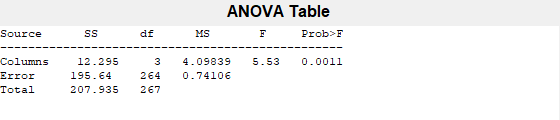

p = 0.0011

tbl = 4×6 cell array
    {'Source' }    {'SS'      }    {'df' }    {'MS'      }    {'F'       }    {'Prob>F'  }
    {'Columns'}    {[ 12.2952]}    {[  3]}    {[  4.0984]}    {[  5.5304]}    {[  0.0011]}
    {'Error'  }    {[195.6402]}    {[264]}    {[  0.7411]}    {0×0 double}    {0×0 double}
    {'Total'  }    {[207.9354]}    {[267]}    {0×0 double}    {0×0 double}    {0×0 double}


stats = struct with fields:
    gnames: [4×1 char]
         n: [67 67 67 67]
    source: 'anova1'
     means: [0.0970 -0.1575 -0.2351 0.3067]
        df: 264
         s: 0.8608


[p,tbl,stats] = anova1(tempPeaks')

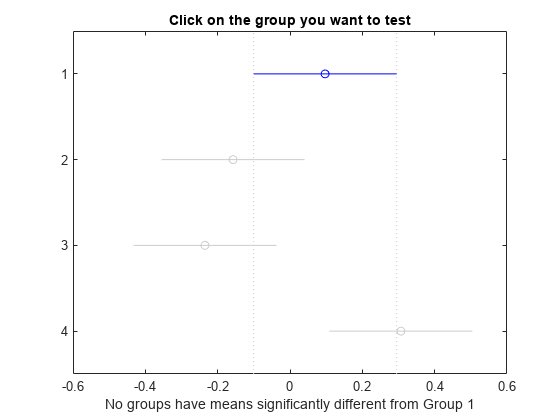

ans =     1.0000    2.0000   -0.1409    0.2545    0.6499    0.5296
    1.0000    3.0000   -0.0633    0.3321    0.7275    0.1584
    1.0000    4.0000   -0.6051   -0.2097    0.1857    0.9584
    2.0000    3.0000   -0.3178    0.0776    0.4730    1.0000
    2.0000    4.0000   -0.8596   -0.4642   -0.0688    0.0120
    3.0000    4.0000   -0.9372   -0.5418   -0.1464    0.0019


multcompare(stats, 'CriticalValueType','bonferroni')